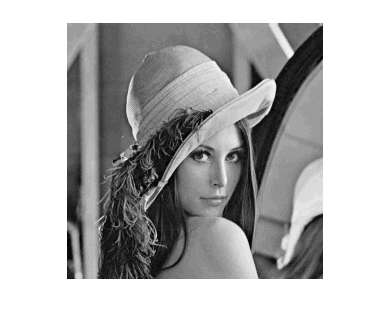

im = (imread('image processing/Lab1/Lena.png'));
min_value = min(min(im));
max_value = max(max(im));
    
M = double(max_value - min_value);

% Quantize with 29 levels
g1=28/M;  
g2=255/28;
quantized1 = round( g1 * ( im - min_value ) ) * g2 ;

% Quantize with 30 levels
g1=29/M;  
g2=255/29;
quantized2 = round( g1 * ( im - min_value ) ) * g2 ;

% Quantize with 31 levels
g1=32/M;  
g2=255/32;
quantized3 = round( g1 * ( im - min_value ) ) * g2 ;

imshow(quantized1);

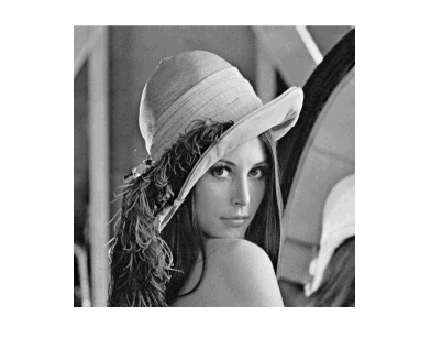

imshow(quantized2);

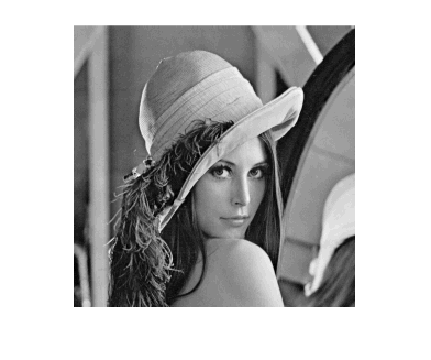

imshow(quantized3);

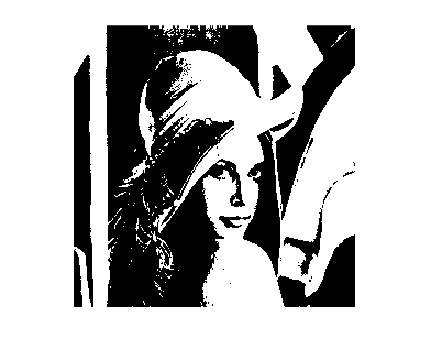


%Binary quantization
binary_quant = uniform_quantizer(im,2);
imshow(binary_quant);